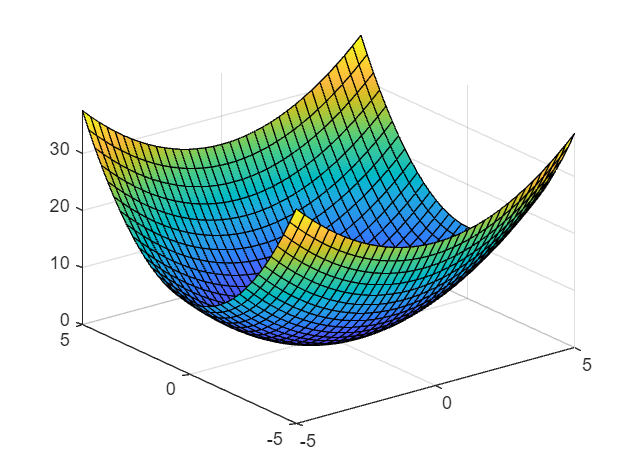

clear
syms x1 x2
eqns1 = [-x1 + 2*x1^2*x2; -x2];
eqns1_mat = @(t, x) [-x(1) + 2*x(1)^2 * x(2); -x(2)];

V1(x1,x2) = x1^2 / 2 + x2^2;

figure;
fsurf(matlabFunction(V1));

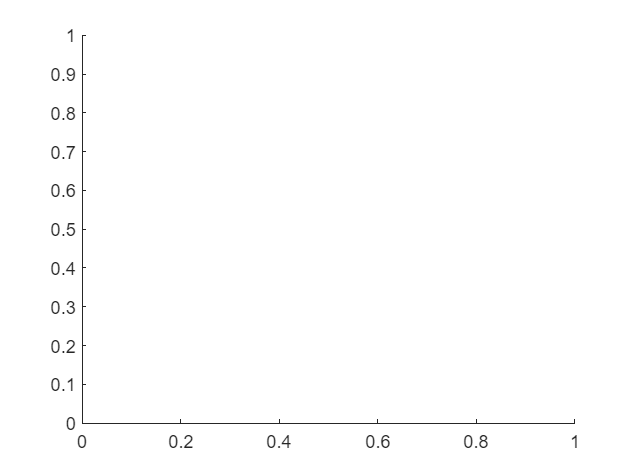

$$dV(x1, x2) = 2\,{x_{1}}^{3}\,x_{2}-{x_{1}}^{2}-2\,{x_{2}}^{2}$$

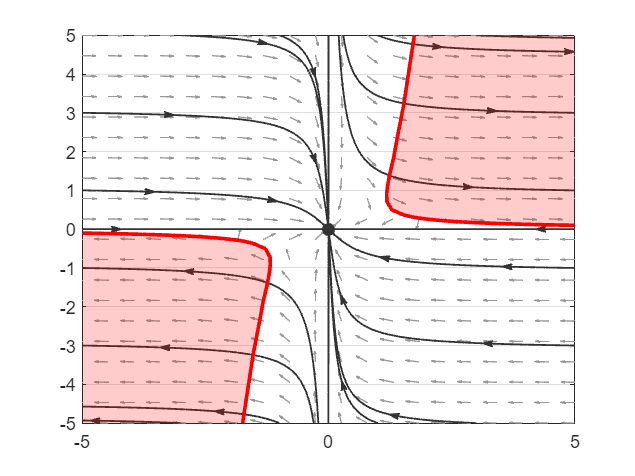

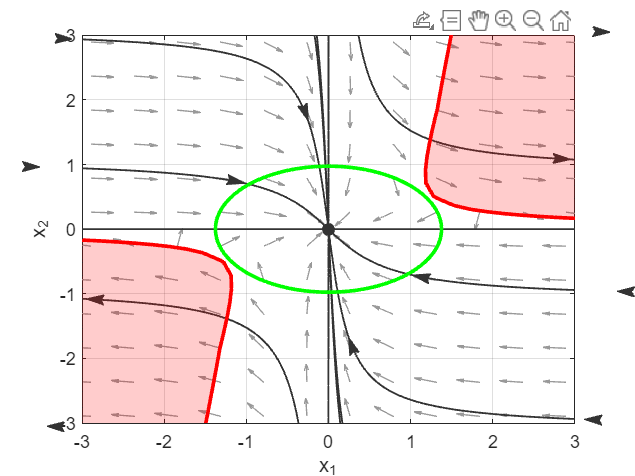


V_Zl1 = draw(eqns1, eqns1_mat, V1, 0.95);

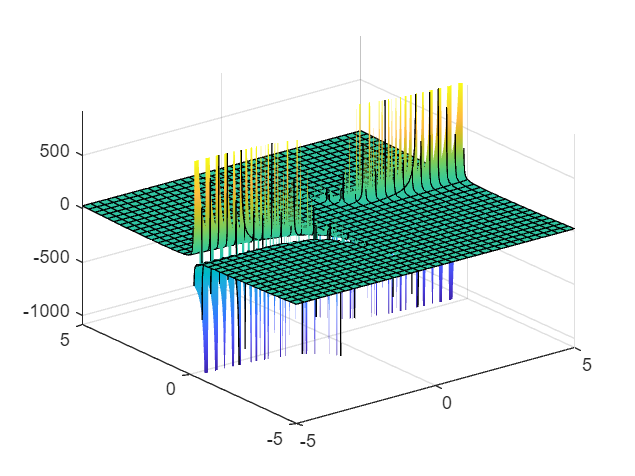

V2(x1,x2) = x1^2 / (1 - x1 * x2) + x2^2;
figure;
fsurf(matlabFunction(V2));

l = 4;
figure; hold on;

plotpp(eqns1_mat);
V_Zl = @(x1,x2) V2(x1, x2) - l;
%fimplicit(V_Zl, 'g', "LineWidth", 2);
%axis([-3 3 -3 3])
%draw(eqns1, eqns1_mat, V2, 4)
% Rozwiązania funkcji kwadratowej x2 = V_Zl(x1) - nie chcie mi się tego
% sprawdzać
foo1(x2) = (x2^3 - l * x2 + sqrt((x2^3- l*x2)^2-4*(x2^2 - l))) / 2;
foo2(x2) = (x2^3 - l * x2 - sqrt((x2^3- l*x2)^2-4*(x2^2 - l))) / 2;
f_y = linspace(-2, 2, 100);
f_x1 = double(foo1(f_y)); 
f_x2 = double(foo2(f_y));

plot(f_x1, f_y, 'b', "LineWidth", 2);
plot(f_x2, f_y,'b', "LineWidth", 2);
axis([-5 5 -5 5]);
fimplicit(V_Zl1, 'g', "LineWidth", 2);
xlabel("x_1");
ylabel("x_2");

% Obszar nieokreśloności funcjkonału L_2
fplot(@(x1) 1/x1, "r", "LineWidth", 2);

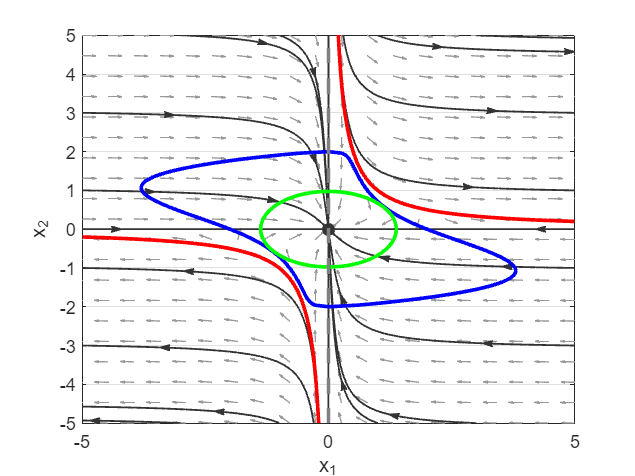

hold off;

dV2(x1,x2) = simplify(jacobian(V2) * eqns1)

$$dV2(x1, x2) = -2\,{x_{1}}^{2}-2\,{x_{2}}^{2}$$

$$dV(x1, x2) = {x_{1}}^{2}\,\left({x_{1}}^{2}-1\right)$$

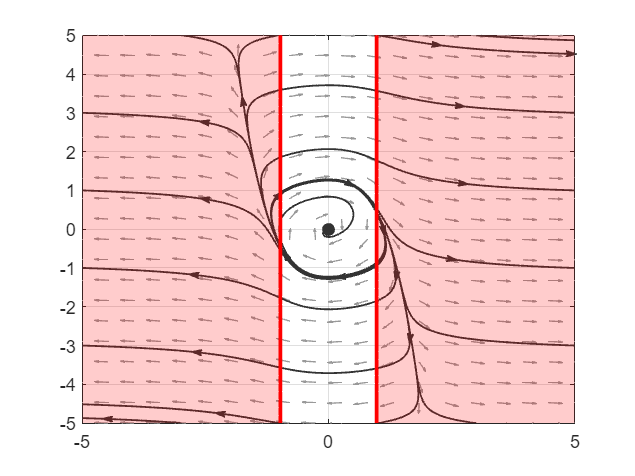

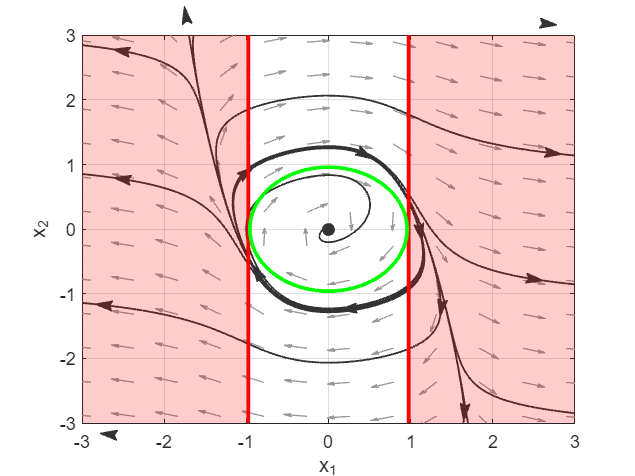

eqns2 = [x2 - x1 + x1^3; -x1];
eqns2_mat = @(t,x) [x(2) - x(1) + x(1)^3; -x(1)];
V3(x1,x2) = (x1^2 + x2^2) / 2;
V_Zl1 = draw(eqns2, eqns2_mat, V3, 0.46);

[eigs, A, bal_points] = lapunov_stab_two_eqns(eqns2)

eigs =   -0.5000 - 0.8660i
  -0.5000 + 0.8660i


A =     -1     1
    -1     0


bal_points =      0     0


function [V_Zl] = draw(eqns, eqns_mat, V, l)
    figure; hold on;
    syms x1 x2
    plotpp(eqns_mat);
    dV(x1,x2) = simplify(jacobian(V) * eqns)
    %fimplicit(dV);
    x = linspace(-5, 5, 50);
    y = x;
    [X, Y] = meshgrid(x,y);
    Z = dV(X,Y);
    fp2=contourf(X,Y,Z, 'r', "LevelList", [0 0], "FaceAlpha", 0.2, "LineWidth", 2);
    colormap([1 0 0; 1 0 0]);
    hold off;
    figure; hold on;
    plotpp(eqns_mat);
    %fimplicit(dV);
    x = linspace(-5, 5, 50);
    y = x;
    [X, Y] = meshgrid(x,y);
    Z = dV(X,Y);
    fp2=contourf(X,Y,Z, 'r', "LevelList", [0 0], "FaceAlpha", 0.2, "LineWidth", 2);
    colormap([1 0 0; 1 0 0]);
    V_Zl = @(x1,x2) V(x1, x2) - l;
    fimplicit(V_Zl, 'g', "LineWidth", 2);
    axis([-3 3 -3 3])
    xlabel("x_1");
    ylabel("x_2");
    hold off;
end

function [eigs, A, bal_points] = lapunov_stab_two_eqns(eqns)
    % Punkty rownowagi
    bal_points = solve(eqns);
    bal_points = double([bal_points.x1, bal_points.x2]);
    eigs = zeros(2, size(bal_points,1));
    % Jakobiany punktow rownowagi
    syms x1 x2 real
    J(x1, x2) = jacobian(eqns);
    A = zeros(2, 2, size(bal_points, 1));
    for i = 1 : size(bal_points, 1)
        point_J = J(bal_points(i, 1), bal_points(i, 2));
        % wartosci wlasne
        eigvals = eig(point_J);
        eigs(:,i) = eigvals;
        % Macierz A ukladu zlinearyzowanego
        A(:,:,i) = double(point_J);
    end
end